# Optimize Model Parameter Fit

A first-order linear system with time delay is a common empirical description of many stable dynamic processes. The equation


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables $y(t)$ and $u(t)$ and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


These variables may be adjusted to match data. An explicit solution to the above equation for each time step $j$ is:


$$y_j = e^{\frac{-\Delta\,t}{\tau_p}} \left(y_{j-1}-y_0\right) + \left(1-e^{\frac{-\Delta\,t}{\tau_p}}\right) \, K_p \, \left(u_{j-\theta_p-1}-u_0\right) + y_0
$$


where $\Delta t$ is the time step length, $y_0$ is the initial output or steady state condition, $u_0$ is the initial input or steady state condition, $y_{j-1}$ and $u_{j-1}$ are values from the prior step and $\theta_p$ is the dead-time measured in number of time steps. 

An alternative to the graphical fitting approach is to use optimization to best match an FOPDT model to data or a more complex model. A common objective is to minimize a sum of squared error that penalizes deviation of the FOPDT model from the data. The optimization algorithm changes the parameters $K_p$, $\tau_p$, $\theta_p$ to best match the data at specified time points. In MATLAB, the `Optimization` task and the `fminsearch` are two ways to optimize multivariable functions in order to regress the parameters of an FOPDT. Unlike a graphical methods for fitting FOPDT models (as addressed in Lesson 6), optimization methods do not require a single step response but may include any sequence of input changes that produce a response in the output.

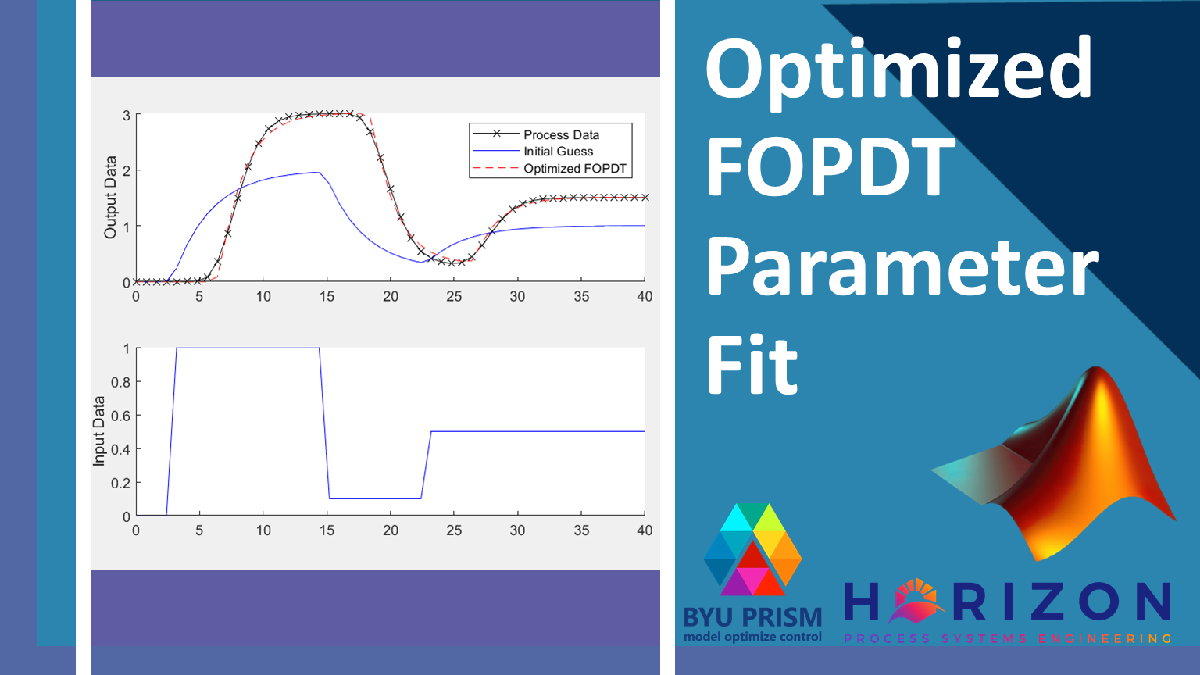

### [View Lecture](https://youtu.be/hbV5buRHLtE)

## Example

In the following exercise, use optimization methods to regress $K_p$, $\tau_p$, and $\theta_p$ to fit a model to process data. To do this, create three functions: 1) an FOPDT function to be used with `ode45` as a function of input values at any given point and $K_p$, $\tau_p$, $\theta_p$ 2) a function to simulate an FOPDT response given $K_p$, $\tau_p$, $\theta_p$ and the time and input vectors 3) an **objective function** which will include an error metric (for example, sum squared of error) between the model, and the data being fitted. The objective function should accept the arguments that will be manipulated ($K_p$, $\tau_p$, $\theta_p$) and return the error. If the model were a perfect representation of the process, the objective function would return a value of 0.0.

This process of fitting FOPDT parameters is shown below: is shown below with both `fminsearch` and the optimization tool box.

### Generate Simulated Data from Model

First, generate the data of the process we will fit an FOPDT model to. This process data is saved in an array `yp`

Specify number of steps:

ns = 50;

Define time points:

t = linspace(0,40,ns+1);
tvals = t;
delta_t = t(2)-t(1);

Define input vector:

u = zeros(1, ns+1);
u(5:20) = 1.0;
u(20:30) = 0.1;
u(30:end) = 0.5;

Simulate Process:

yp = sim_process_data(u, delta_t, ns);

Graph:

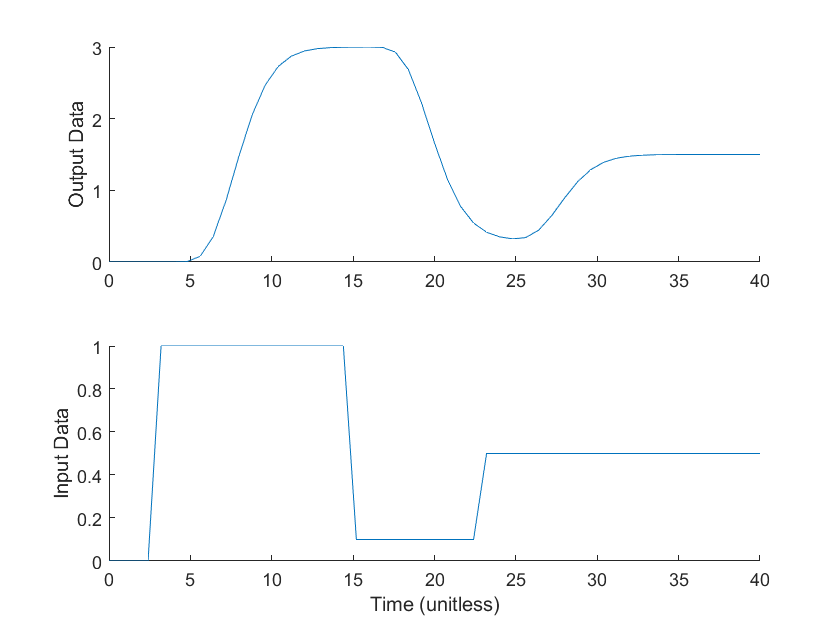

figure(1);
title('Process Data')
subplot(2,1,1);
hold on
plot(t, yp);
ylabel('Output Data')


subplot(2,1,2);
hold on
plot(t, u);
ylabel('Input Data')
xlabel('Time (unitless)')

## Method 1: fminsearch

`fminsearch` is a method naitive to MATLAB which finds the minimum of an unconstrained function without the use of gradients (derivatives). It requires a function with an input of the parameters being optimized and an initial guess of those parameters. For constrained optimization try [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) in the optimization toolbox.

x0 = zeros(1,3);
x0(1) = 2; %Km
x0(2) = 3; %taum
x0(3) = 0; %thetam

solution = fminsearch(@(x)objective(x, t, u, yp), x0)

solution =     3.0148    1.8606    3.7149


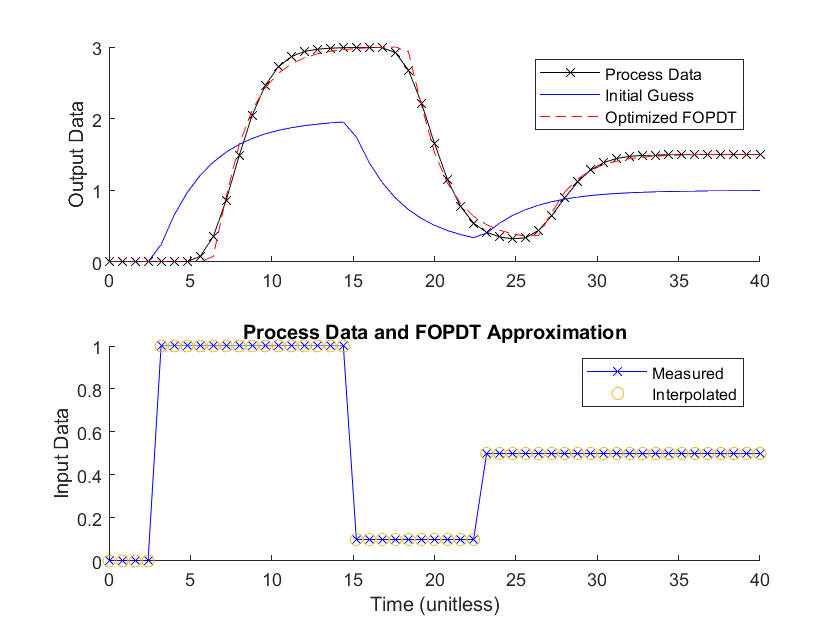


ym1 = sim_model(x0, t, u, yp);
ym2 = sim_model(solution, t, u ,yp);

figure(2);
title('Process Data and FOPDT Approximation')
subplot(2,1,1)
hold on
p1 = plot(t, yp,'kx-');
p2 = plot(t, ym1, 'b-');
p3 = plot(t, ym2, 'r--');
legend([p1, p2, p3], {'Process Data', 'Initial Guess', 'Optimized FOPDT'})
ylabel('Output Data')

subplot(2,1,2)
hold on
p4 = plot(t,u,'bx-');
p5 = plot(t, interp1(t, u, t), 'o');
legend([p4, p5], {'Measured', 'Interpolated'})
ylabel('Input Data')

### Method 2: Optimization Task

Create a parametrized function (see `objective_parametrized` below) so that the optimize block only requires

objective_parametrized = @(x)objective(x, t, u, yp)

objective_parametrized = function_handle with value:
    @(x)objective(x,t,u,yp)


xmax = [10, 10, 10]

xmax =     10    10    10


xmin = [-10, 0, 0]

xmin =    -10     0     0


% Set nondefault solver options
options = optimoptions('lsqnonlin','FunctionTolerance',1e-10,'Display',...
    'iter','PlotFcn',{'optimplotx','optimplotfunccount','optimplotresnorm',...
    'optimplotfval','optimplotfirstorderopt'});

% Solve
[solution,objectiveValue] = lsqnonlin(objective_parametrized,x0,xmin,xmax,...
    options);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           4         1236.44           0.111         0.01
     1           8         388.874           0.697        0.001        1.28347
     2          12         135.968           0.495       0.0001        1.08849
     3          16         51.1972            3.73        1e-05       0.790134
     4          20          32.034            1.17        1e-06       0.732759
Objective function returned NaN; trying a new point...
     5          31          22.987            4.77           10       0.963004
     6          35         8.02119            5.94            1       0.433621
     7          40         5.59338            12.2           10        0.41406
     8          44         4.19801            5.83            1       0.324255
     9          50         3.32403            3.58          100      0.0724825
    10    


% Clear variables
clearvars options
disp(solution)

    3.0163    1.8743    3.7015



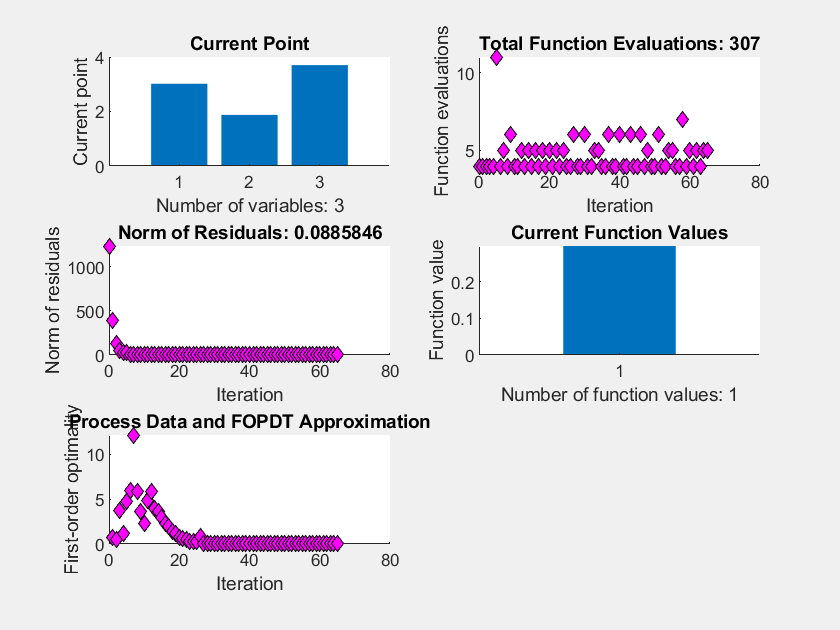

ym3 = sim_model(solution, t, u, yp);

figure(3);
title('Process Data and FOPDT Approximation')

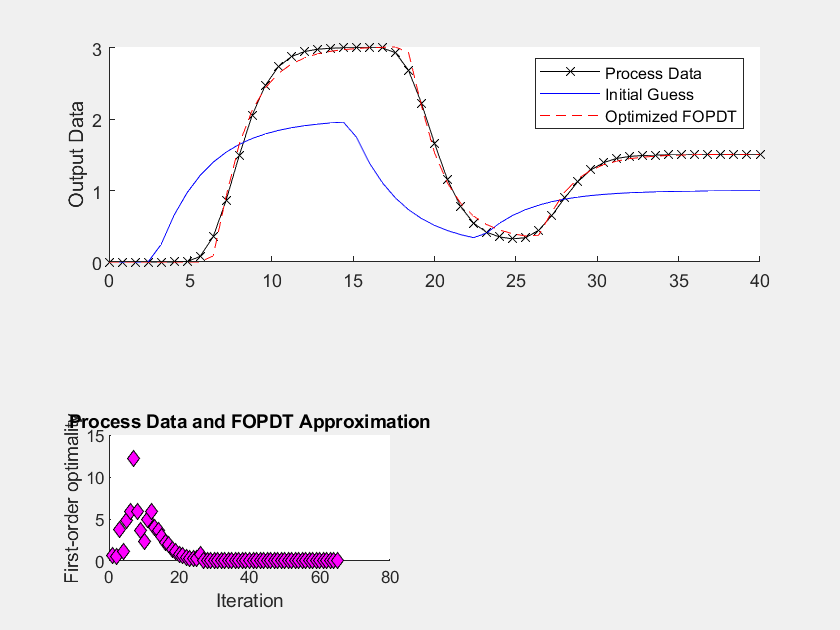

subplot(2,1,1)
hold on
p1 = plot(t, yp,'kx-');
p2 = plot(t, ym1, 'b-');
p3 = plot(t, ym3, 'r--');
legend([p1, p2, p3], {'Process Data', 'Initial Guess', 'Optimized FOPDT'})
ylabel('Output Data')

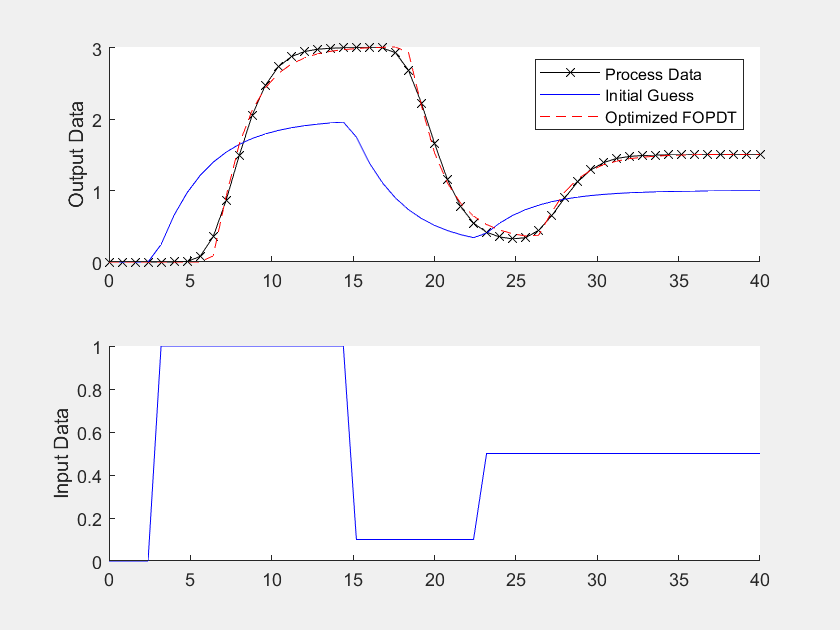


subplot(2,1,2)
hold on
p4 = plot(t,u,'b-');
ylabel('Input Data')

#### Functions for creating process data to fit FOPDT to:

`process` creates the differential equations to be integrated

`sim_process_data` creates a set of data given input data. It includes locally initialized gain and time constant

function dydt = process(~, y, n, u, Kp, taup)
    % arguments
    %  y[n] = outputs
    %  t    = time
    %  n    = order of the system  
    %  u    = input value
    %  Kp   = process gain
    %  taup = process time constant
    % equations for higher order system
    dydt = zeros(n,1);
    %size of y is determined by inital conditions
    % calculate derivative
    dydt(1,1) = (-y(1) + Kp * u)/(taup/n);
    for i = 2:n
       dydt(i,1) = (-y(i) + y(i-1))/(taup/n);
    end
end

function yp = sim_process_data(u, delta_t, ns)
    % higher order process
    n=10;       % order
    Kp=3.0;    % gain
    taup=5.0;   % time constant
      yp = zeros(1,ns+1);  % storage for predictions or data
    for i = 1:ns+1
        if i==1
            yp0 = zeros(1, n);
        end
        ts = [delta_t*(i-1),delta_t*i];
        [~, y] = ode45(@(t, y) process(t, y, n, u(i), Kp, taup), ts, yp0);  
        yp0 = y(end,:);
        yp(i) = y(2, n);
    end
end

#### Functions for FOPDT Model:

% define first-order plus dead-time approximation    
function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp1, u1)
    % arguments
    %  t      = time
    %  y      = output
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    %  yp1    = initial output value
    %  u1     = initial input value

    try
        if (t-thetam) <= 0
            um = interp1(tvals, u, 0.0);%% IS A FUNCTION
        else
            um = interp1(tvals, u, t-thetam); %% IS A FUNCTION
        end
    catch 
        disp('Error with time extrapolation: ' + t )

        um = u1;
    end
    % calculate derivative
    dydt = (-(y-yp1) + Km * (um-u1))/taum;
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(x, time_, u_, yp_)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    
    ns = length(time_);
    delta_t = time_(2) - time_(1);
    yp1 = yp_(1);
    u1 = u_(1);
    
    % storage for model values
    ym = zeros(1, ns);  % model
    % initial condition
    ym(1) = yp1;
    % loop through time steps    
    for i = 1:ns-1
        ts = [delta_t*(i-1),delta_t*i];
        [~, y1] = ode45(@(t, y) fopdt(t, y, u_, time_, Km,taum,thetam, yp1, u1), ts, ym(i));
        ym(i+1) = y1(end);
    end
end

function obj = objective(x_arg, time_, u_, yProcess)
    % simulate model
    ym = sim_model(x_arg, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2);    
end
